# Lista 3

## **Wstęp**

**Funkcja **`quiver(x,y,u,v,S)`**:**

rysuje wektor na płaszczyźnie o początku w (x, y) i składowych (u, v), S kontroluje skalowanie.

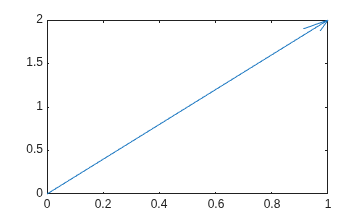

quiver(0,0,1,2,1)

**Funkcja **`quiver3(x,y,z,u,v,w,S)`**:**

rysuje wektor 3D o początku w (x, y, z) i składowych (u, v, w), S kontroluje skalowanie.

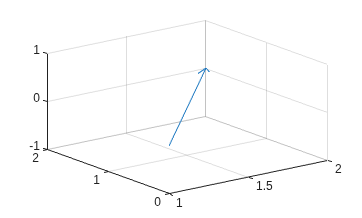

quiver3(1,0,0, 1,2,0 ,1)

**Instrukcja **`hold on/hold off`**:**

po wpisaniu instrukcji `hold on` kolejne elementy będą dorysowywyane, aż zostanie wpisana instrukcja `hold off`.

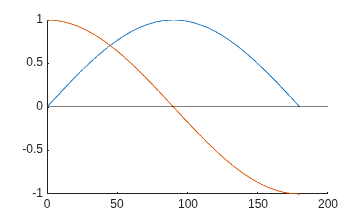

clf()                       % czyści rysunek
kat = 0:2:180;
hold on
plot(kat, sind(kat))        % wykres funkcji sin()
plot(kat, cosd(kat))        % wykres funkcji cos()
plot([0 200], [0 0], 'k')   % rysowana oś x w y=0
hold off

**Funkcja **`subplot(m,n,p)`**:**

dzieli okno rysunku na $m\times n$  podwykresów, gdzie $m$ to liczba wierszy a $n$ to liczba kolumn. Następnie wybiera *p*-ty wykres, w którym wykonywany jest rysunek.

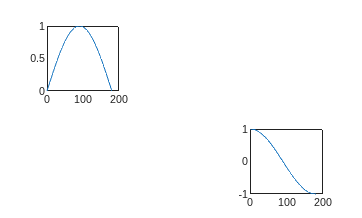

clf()
kat = 0:2:180;

% Dwa rysunki w 1 wierszu. 
% W pierwszym będzie sin()  
subplot(2,3,1) 
plot(kat, sind(kat))        % wykres funkcji sin()

% W drugim będzie cos()  
subplot(2,3,6)
plot(kat, cosd(kat))        % wykres funkcji cos()

**Funkcja **`text(x,y,'mój napis')`**:**

wyświetla tekst *moj napis* w miejsu wykresu o współrzędnych *x* i *y*.

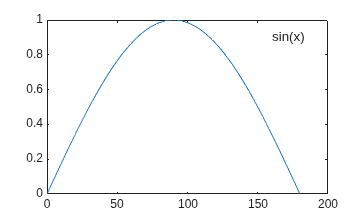

clf()
kat = 0:2:180;
plot(kat, sind(kat))        % wykres funkcji sin()
text(160,0.9,'sin(x)')

**Funkcja num2str**`(x)`**:**

zamienia liczbę rzeczywistą na tekst.

clf()
kat = 0:2:180;
plot(kat, sind(kat))        % wykres funkcji sin()
x = sind(45)

x = 0.7071

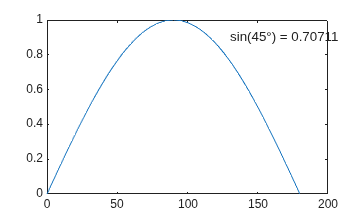

text(130,0.9,['sin(45°) = ' num2str(x)])

## **Zadania**

**Zad. 1**. Znajdź składowe $x$ i $y$ wektora przemieszczenia o 25 m pod kątem 210°. Narysuj wektor przemieszczenia i jego składowe

r = 25

r = 25

x = r*cosd(210)

x = -21.6506

y = r*sind(210)

y = -12.5000

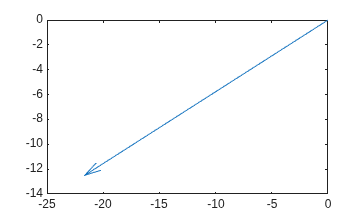


quiver(0,0, x,y, 1)

**Zad. 2.** Wykorzystując składowe, znajdź całkowite przemieszczenie, jeśli pierwsze nastąpiło o 2 m pod kątem 45°, a drugie o 4 m pod kątem 127°. Na lewym wykresie umieść oba wektory opisujące przemieszczenia i wektor przedstawiający ich sumę. Na prawym wykresie umieść składowe wektorów przemieszczenia i wektor ich sumy. Końcowy rysunek powinien jak najbardziej przypominać ten załączony poniżej. Współrzędne każdego z wektorów zadania powinny być przechowywane w zmiennej typu wektor i na całych wektorach powinny być wykonywane operacje.

 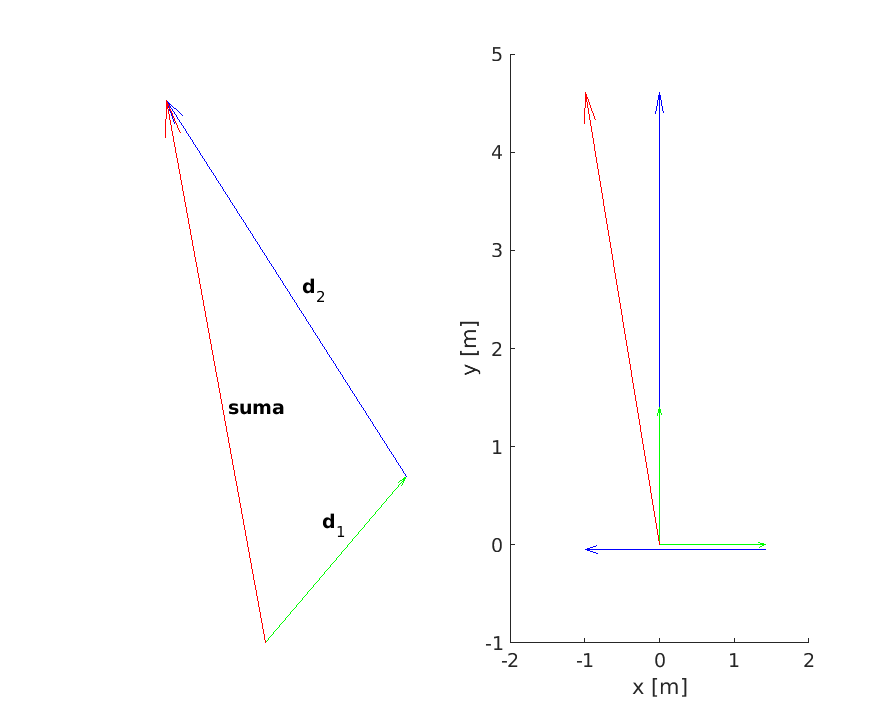

clf()
r_a = 2

r_a = 2

r_b = 4

r_b = 4

alpha = 45

alpha = 45

beta = 127

beta = 127

A = [r_a*cosd(45) r_a*sind(45)]

A =     1.4142    1.4142


B = [r_b*cosd(127) r_b*sind(127)]

B =    -2.4073    3.1945



C = A + B

C =    -0.9930    4.6088



Z = sqrt(C(1)^2+C(2)^2)

Z = 4.7145

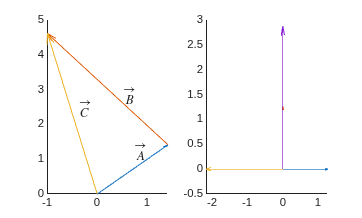



subplot(1,2,1)

hold on
quiver(0,0, A(1),A(2), 1)
text( ...
    mean([A(1);0]), ...
    mean([0;A(2)])+0.5, ...
    '$\vec{A}$', 'Interpreter', 'latex')

quiver(A(1),A(2), B(1),B(2), 1)
text( ...
    -mean([A(1);B(1)]), ...
    mean([A(2);B(2)])+0.5, ...
    '$\vec{B}$', 'Interpreter', 'latex')

quiver(0,0, C(1),C(2), 1)
text( ...
    mean([0;C(1)])+0.1, ...
    mean([C(2);0])+0.15, ...
    '$\vec{C}$', 'Interpreter', 'latex')


hold off

subplot(1,2,2)
hold on
quiver(0,0 ,A(1),0)
quiver(0,0 ,0,A(2))

quiver(0,0 ,B(1),0)
quiver(0,0 ,0,B(2))
hold off

**Zad. 3.** Dla wektorów przedstawionych na rysunku znajdź $\vec{\;A} +\vec{\;B}$, $\vec{\;A} -\vec{\;B}$, $-\vec{\;A} +\vec{\;B}$, $\vec{\;A} +\vec{\;B} +\vec{\;C}$ i  $\vec{\;A} +\vec{\;B} -\vec{\;C}$. Wynik przedstaw w postaci odpowiednich wartości wektorów wyświetlonych na ekranie oraz graficznie. Podziel rysunek na odpowiednią liczbę podwykresów, aby był on czytelny. Na każdym wykresie opisz wykresy, jaka operacja jest wykonywana oraz długość wynikowego wektora.

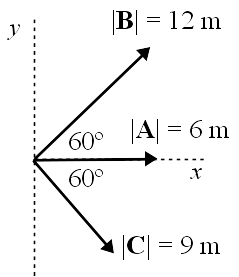

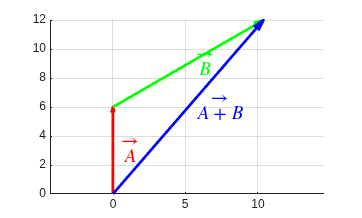

clf()

r_a = 6
r_b = 12
r_c = 9

A = [r_a*cosd(90) r_a*sind(90)]
B = [r_b*cosd(30) r_b*sind(30)]
C = [r_c*cosd(120) r_c*sind(120)]

hold on
quiver(0,0, A(1),A(2), 1,"r--")
text( ...
    mean([A(1);0])+0.3, ...
    mean([0;A(2)]), ...
    '$\vec{A}$', 'Interpreter', 'latex','Color','r')

quiver(A(1),A(2), B(1),B(2) ,1,"g--")
text( ...
    mean([A(1);B(1)])+0.3, ...
    mean([A(2);B(2)]), ...
    '$\vec{B}$', 'Interpreter', 'latex','Color','g')

result = A + B
quiver(0,0, result(1),result(2),1,"b")
text( ...
    -mean([0;C(1)]), ...
    mean([0;C(2)]), ...
    '$\vec{A+B}$', 'Interpreter', 'latex','Color','b')

hold off



